2)

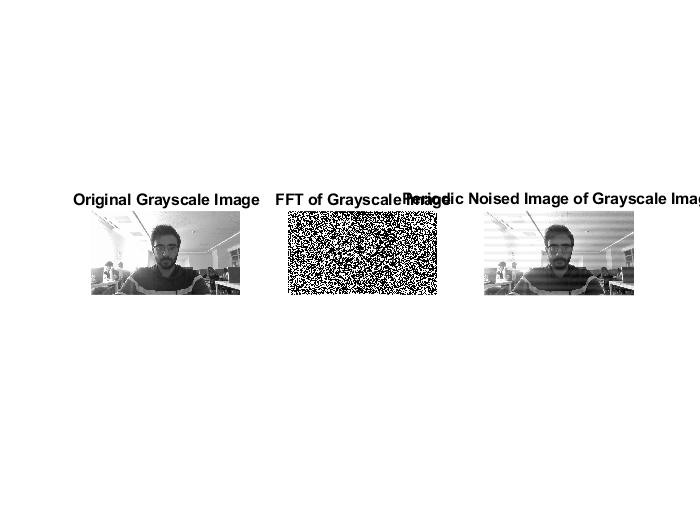

tic;
subplot(1,3,1);
ahmet=imread('C:\Users\ahmet\Desktop\4.sınıf\image\mp4\ahmet.jpg');
ahmet_gray=rgb2gray(ahmet);
yoldas=im2double(ahmet_gray); 
imshow(yoldas);
title('Original Grayscale Image','fontsize', [12]);
 
subplot(1,3,2);
[x,y]=size(yoldas); 
fft_ahmet=fft2(yoldas,x,y);
imshow(real(fft_ahmet));
title('FFT of Grayscale Image','fontsize', [12]);
 
 
subplot(1,3,3);
fft_ahmet(12,1)=47000;
fft_ahmetNoised=ifft2(fft_ahmet);
imshow(real(fft_ahmetNoised));
title('Periodic Noised Image of Grayscale Image');

 
toc;

Elapsed time is 0.543853 seconds.
